C = [3 4 5 6 6; 3 3 4 5 6;2 3 3 4 5; 1 2 3 3 4;1 1 2 3 3];
V = [1 2 3 4 5;2 4 6 8 10;3 6 9 12 15; 4 8 12 16 20; 5 10 15 20 25];
ax=axes 

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hold on
[X,Y] = meshgrid(1:size(C,1),1:size(C,2))

X =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


Y =      1     1     1     1     1
     2     2     2     2     2
     3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5


h = imagesc(X(:),Y(:),flipud(C))

h =   Image with properties:

           CData: [5×5 double]
    CDataMapping: 'scaled'

  Show all properties


cmap = [0 1 0;0.5 1 0.5;1 1 0;1 1 0.6;1 0.5 0.5;1 0 0];
%see notes from the cmap/colormap from 3 by 3 matrix option. 
str = sprintfc('%d',V(:))

str = 25×1 cell array
    {'1' }
    {'2' }
    {'3' }
    {'4' }
    {'5' }
    {'2' }
    {'4' }
    {'6' }
    {'8' }
    {'10'}
    {'3' }
    {'6' }
    {'9' }
    {'12'}
    {'15'}
    {'4' }
    {'8' }
    {'12'}
    {'16'}
    {'20'}
    {'5' }
    {'10'}
    {'15'}
    {'20'}
    {'25'}


text(X(:),Y(:),str)
RowLabels = {'very unlikely','unlikely','possible','likely','very likely'};
ColLabels = {'negligible','minor','moderate','significant','severe'};
set(gca,'xtick',unique(X),...
    'ytick',unique(Y),...
    'yticklabels',RowLabels,...
    'xticklabels',ColLabels)
cb = colorbar(ax,'location','southoutside')

cb =   ColorBar with properties:

    Location: 'southoutside'
      Limits: [1 6]
    FontSize: 9
    Position: [0.1417 0.1524 0.7631 0.0508]
       Units: 'normalized'

  Show all properties


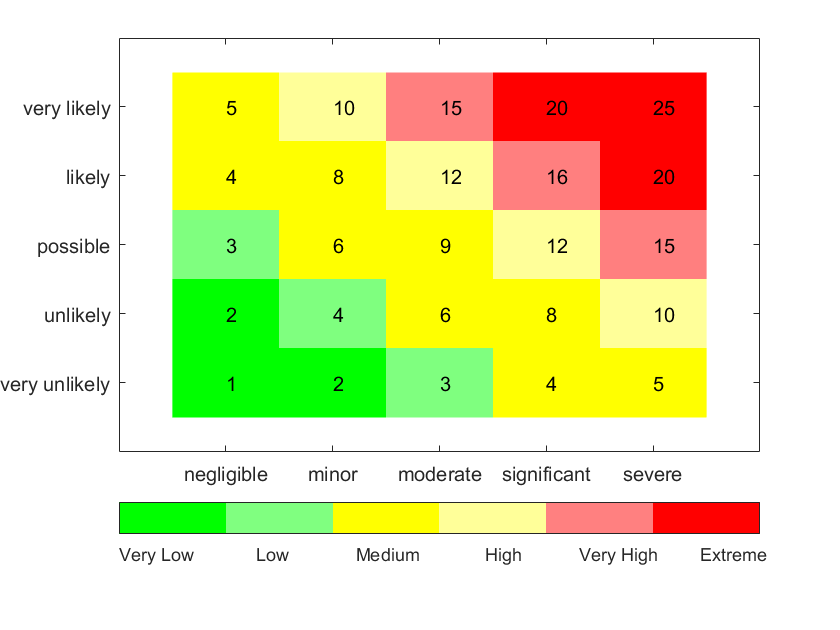

set(cb,'ticks',[1.3 2.2 3.1 4 4.9 5.8],...
    'ticklabels',{'Very Low','Low','Medium','High','Very High','Extreme'},...
    'ticklength',0)
box on
set(ax,'layer','top')
colormap(cmap)

% else 
%     disp(['you have entered the wrong input, please input 3 for 3 by 3 matrix' ...
%         ' and 5 for 5 by 5 matrix']);
    % need to make this IF/ELSEIF statement a closed loop, so that if the
    % user noticed that they have the wrong input they can goback and fix
    % it.

Please Enter the Risk Probability

Probability_2 = 2;

Please Enter the Risk Severity

Severity_2 = 4;

The Risk Level of this Hazard is:

Risk_level_5_by_5 = Probability_2 * Severity_2;
if Risk_level_5_by_5 < 3;
    Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_5_by_5), ' .',...
    'Score 1-2： Negligible Risk Level.'];
    disp(Result_3);
elseif (2 < Risk_level_5_by_5)&& (Risk_level_5_by_5 <5); 
    Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_5_by_5), ' .',...
        'Score 3-4: Minor Level, recommending reduce the level and report to the facility.'];
    disp(Result_3);
elseif (4 < Risk_level_5_by_5)&& (Risk_level_5_by_5 <10);
    Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_5_by_5), ' .',...
        'Score 5-9: Medium Level, recommending reduce the level and report to the facility with Caution.'];
    disp(Result_3);
elseif (9 < Risk_level_5_by_5)&& (Risk_level_5_by_5 <15);
    Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_5_by_5), ' .',...
        'Score 10-12: Significant Level, Action Required! recommending reduce the level and report to the facility with Caution.'];
    disp(Result_3);
elseif (14 < Risk_level_5_by_5)&& (Risk_level_5_by_5 <17);
    Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_5_by_5), ' .',...
        'Score 15-16: Very High Level, Action Required! recommending reduce the level and report to the facility with Caution.'];
    disp(Result_3);
else
    Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_5_by_5), ' .',...
    'Score 20-25: Extreme Level! Do Not Fly! Immediate Action Required! Report to the facility and seek actions.'];
    disp(Result_3);
end

The Risk level of this hazard is 8 .Score 5-9: Medium Level, recommending reduce the level and report to the facility with Caution.


% This is the Original 3 BY 3 Matrix IF/ELSEIF code, do not erase!!!!
% if Risk_level_3_by_3 < 3;
%     Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_3_by_3), ' .',...
%     'Score 1-2： Negligible Risk Level.'];
%     disp(Result_3);
% elseif (2 < Risk_level_3_by_3)&& (Risk_level_3_by_3 <6); 
%     Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_3_by_3), ' .',...
%     'Score 3-4: Medium Level, recommending reduce the level and report to the facility.'];
%     disp(Result_3);
% else
%     Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_3_by_3), ' .',...
%     'Score 6-9: Immediate Action Required: Report to the facility and seek actions.'];
%     disp(Result_3);
% end
% Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_5_by_5), ' .'];
% disp(Result_3);

%control options. dropdown list of options to reduce the color. 